# Discrete Time Signals and Systems

## Theoretical aspects

- Sampling theorem

- Mapping the s plane into the z plane

- Recursive relations (equations with differences)

- Unit delay operator

## Aims

Avoid bad sampling: Aliasing and folding effects.

Recognize the behavior of discrete time systems depending on their poles location.

## Sampling continuous time signals and systems

### Establishing the sampling period

Sampling theorem (Shannon's Theorem):


$$f_s >2f_{\max }$$


(fs: sampling frequency, fmax the maximum frequency in the signal spectrum)

When the sampling theorem is not respected, it will appear false frequencies inducing aliasing folding effects. In the next graphic can be seen the aliasing effect.

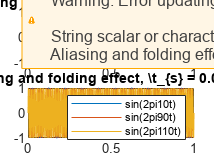

%% establishing the sampling period
f1 = 10; f2 = 90; f3 = 110;
T1 = 0.01; t = 0:T1:1; % T1 not sufficiently small

figure,
subplot(2,1,1); 
plot(t,sin(2*pi*f1*t),t,sin(2*pi*f2*t),t,sin(2*pi*f3*t))
title('Aliasing and folding effect, \t_{s} = 0.01 sec','Interpreter','latex')
legend('sin(2pi10t)','sin(2pi90t)','sin(2pi110t)')

T2 = 0.001; t = 0:T2:1; 
subplot(2,1,2); 
plot(t,sin(2*pi*f1*t),t,sin(2*pi*f2*t),t,sin(2*pi*f3*t))
title('Aliasing and folding effect, \t_{s} = 0.001 sec','Interpreter','latex')
legend('sin(2pi10t)','sin(2pi90t)','sin(2pi110t)')

### Mapping the 's' plane into the 'z' plane

The mathematical transformation between the continuous time and discrete time approach is presented below:


$$z=e^{{\mathrm{sT}}_s } ,\mathrm{Ts}-\mathrm{the}\;\mathrm{sampling}\;\mathrm{period}$$


Using this important results, the correspondences between the two planes can be made without difficulties using the Matlab graphical facilities. 

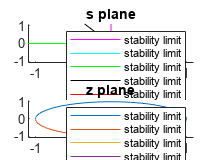

%% mapping the s plane into the z plane
T = 1e-3;

s1 = 1i*linspace(0,pi/T,1e3);
s2 = -s1;
s3 = -linspace(0,pi/T,1e3);
s4 = -(1-1i)*linspace(0,pi/T,1e3);
s5 = (-1-1i)*linspace(0,pi/T,1e3);

z1 = exp(s1*T);
z2 = exp(s2*T);
z3 = exp(s3*T);
z4 = exp(s4*T);
z5 = exp(s5*T);

figure,
subplot(2,1,1); hold on;
axis([-1.1 1.1 -1.1 1.1]);
plot(real(s1),imag(s1),'m');
plot(real(s2),imag(s2),'cyan');
plot(real(s3),imag(s3),'g');
plot(real(s4),imag(s4)*pi,'black');
plot(real(s5),imag(s5)*pi,'r');
plot(real(s3),imag(s3)+pi/T,'b');
plot(real(s3),imag(s3)-pi/T,'Color',[0.5 0.35 0.25]);
title('s plane');
legend('stability limit','stability limit','stability limit','stability limit','stability limit');

subplot(2,1,2); hold on;
axis([-1.1 1.1 -1.1 1.1]);
plot(real(z1),imag(z1))
plot(real(z2),imag(z2));
plot(real(z3),imag(z3));
plot(real(z3),imag(z4));
plot(real(z3),imag(z5));
% plot(real(z3),imag(3),'Color',[205 127 50]./255);
% plot(real(z4),imag(z4),'Color',[0.8500 0.3250 0.0980]);
title('z plane');
legend('stability limit','stability limit','stability limit','stability limit','stability limit');


% damping factor > 1? [UNDERDAMPED]